## **Machine Learning Coffee Hour**

**March 13th, 2020**

**Aahana Bajracharya**

## **Common distributions**

**1.Uniform distribution (Continuous)**

Probability Density Function, ${\displaystyle f(x)={\frac {1}{b-a}}}
$

x = -3:0.01:3;
a = -1;
b = 1;
y = unifpdf(x,a,b);
figure;
plot(x,y);
hold on;
y = unifpdf(x,2*a,b);
plot(x,y);
ylim([0 1]);
xlabel('X');
ylabel('Probability Density');
legend ('Distribution 1','Distribution 2');


**2.Exponential distribution (Continuous)**

Probability Density Function, ${\displaystyle f(x)=\lambda e^{-\lambda x}}
$

Mean = $${\displaystyle {\frac {1}{\lambda}}}$
$ ; $${\displaystyle \lambda}$$ is also known as the rate parameter

x = 0:0.01:6;
lambda = 2;
y = exppdf(x,lambda);
figure;
plot(x,y);
hold on;
y = exppdf(x,2*lambda);
plot(x,y);
xlabel('X');
ylabel('Probability Density');
legend ('Distribution 1','Distribution 2');

**3.Gaussian/Normal distribution (Continuous)**

Probability Density Function, ${\displaystyle f(x)={\frac {1}{\sigma {\sqrt {2\pi }}}}e^{-{\frac {1}{2}}\left({\frac {x-\mu }{\sigma }}\right)^{2}}}$

Mean = $\mu $ ; Standard Deviation = ${\displaystyle \sigma }$

x = -3:0.01:3;
mu= 0;
sigma= 1;
y = normpdf(x,mu,sigma);
figure;
plot(x,y);
hold on;
y = normpdf(x,mu,2*sigma);
plot(x,y);
xlabel('X');
ylabel('Probability Density');
legend ('Distribution 1','Distribution 2');

**4.Binomial distribution (Discrete)**

Probability Mass Function, ${\displaystyle f(k,n,p)=\Pr(k;n,p)=\Pr(X=k)={{n}\choose{k}}p^{k}(1-p)^{n-k}}$


$${\displaystyle {n}\choose{k}}={\frac {n!}{k!(n-k)!}}}$$


Number of trials = n ; 

Probability of success for each trial = p ;  

Number of successes = k

Mean = np

x = 0:40;
n = 20;
p = 0.5;
y = binopdf(x,n,p);
figure;
scatter(x,y);
hold on;
y = binopdf(x,2*n,p);
scatter(x,y);
xlabel('Number of successes (k)');
ylabel('P(X=k)');
legend ('Distribution 1','Distribution 2');

**5. Poisson Distribution (Discrete)**

Probability Density Function, $\!f(k;\lambda )=\Pr(X=k)={\frac {\lambda ^{k}e^{-\lambda }}{k!}}$

Mean = $${\displaystyle \lambda}$$; Number of occurences = k 

x = 0:40;
lambda = 2;
y = poisspdf(x,lambda);
figure;
scatter(x,y);
hold on;
y = poisspdf(x,2*lambda);
scatter(x,y);
xlabel('Number of occurences (k)');
ylabel('P(X=k)');
legend ('Distribution 1','Distribution 2');

**6.Gamma Distribution (Continuous)**

Probability Density Function, ${\displaystyle f(x;\alpha ,\beta ) ={\frac {\beta ^{\alpha }x^{\alpha -1}e^{-\beta x}}{\Gamma (\alpha )}}\quad {\text{ for }}x>0\quad \alpha ,\beta >0}$

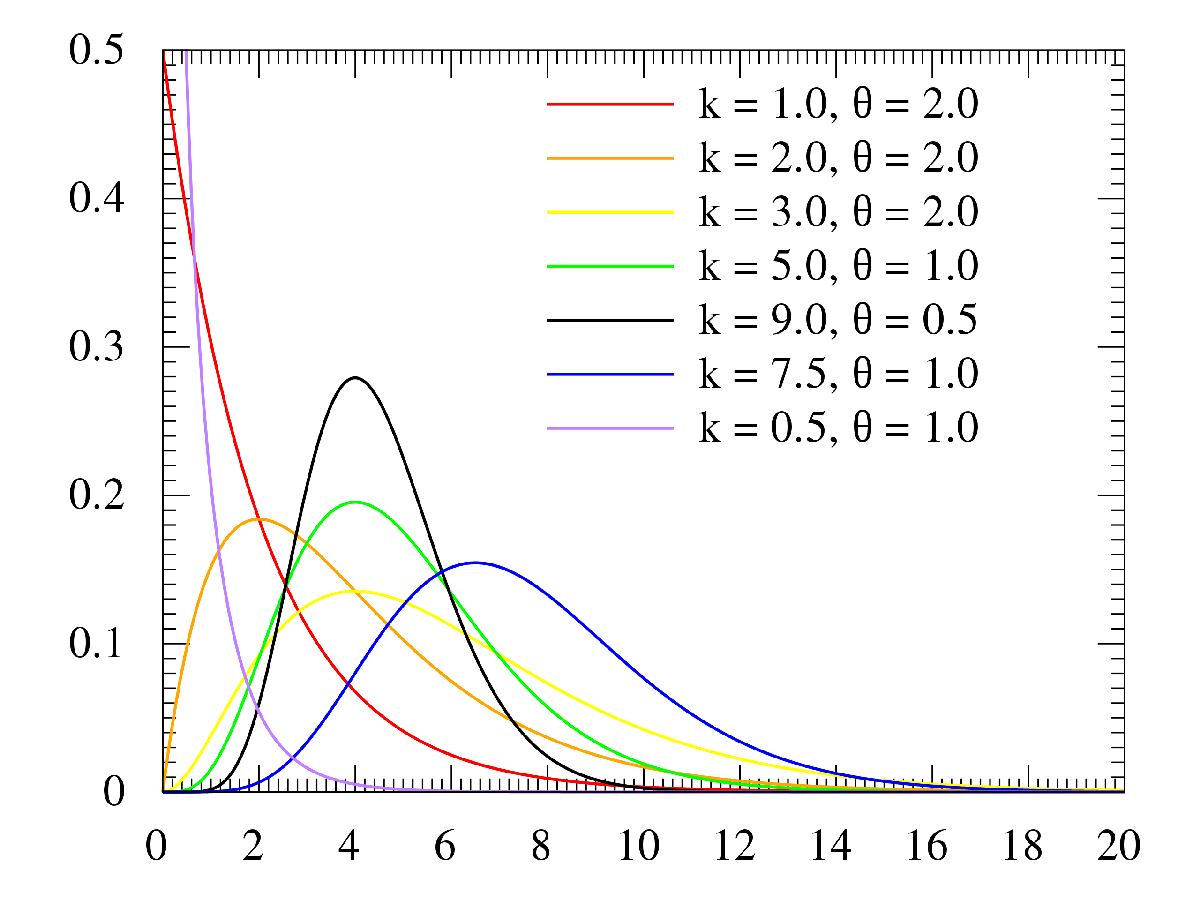

**7.Beta Distribution (Continuous)**

Probability Density Function, ${\displaystyle f(x;\alpha ,\beta) = {\frac {1}{B(\alpha, \beta)} x^{\alpha -1} (1 - x)^{\beta -1}$

$\alpha , \beta $ are shape parameters